m=mobiledev

m = mobiledev with properties:

                      Device: 'Galaxy A52s 5G'
                   Connected: 1
                     Logging: 0
            AvailableCameras: {'back' 'front'}
            InitialTimestamp: ''

   AccelerationSensorEnabled: 1
AngularVelocitySensorEnabled: 1
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0
Show all properties

m.AccelerationSensorEnabled = 1;
m.Logging = 1;


[a, t] = accellog(m);

plot(t, a);
legend('X', 'Y', 'Z');

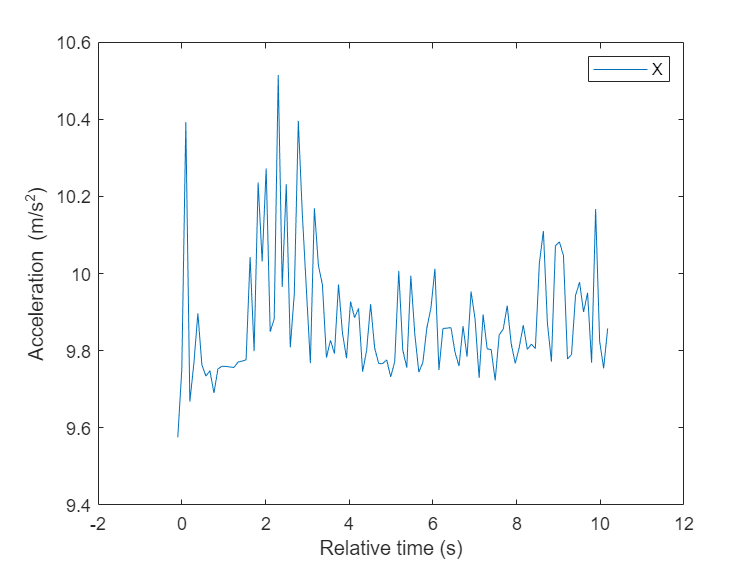

xlabel('Relative time (s)');
ylabel('Acceleration (m/s^2)');


% t(end)
% length(t)
% a(1,2)

for i= 1:length(t)
    if i==1
        vx(i)= 0+a(i,1)*(t(end)/length(t));
        vy(i)= 0+a(i,2)*(t(end)/length(t));
    else
        vx(i)= vx(i-1)+a(i,1)*(t(end)/length(t));
        vy(i)= vy(i-1)+a(i,2)*(t(end)/length(t));
    end
end
plot(t, vx);hold

'vx'은(는) 인식할 수 없는 함수 또는 변수입니다.

plot(t, vy);hold off
for i= 1:length(t)
    px(i)= vx(i)*(t(end)/length(t));
    py(i)= vy(i)*(t(end)/length(t));
end
plot(px,py)
plot(t,py)
plot(t,px)


m.Logging = 0;

mobiledev 객체가 Galaxy A52s 5G 기기에 연결되지 않았습니다. Galaxy A52s 5G에서 MATLAB Mobile이 실행 중이고 인터넷에 연결되어 있는지 확인하십시오.

m.AccelerationSensorEnabled = 0;
clear m;




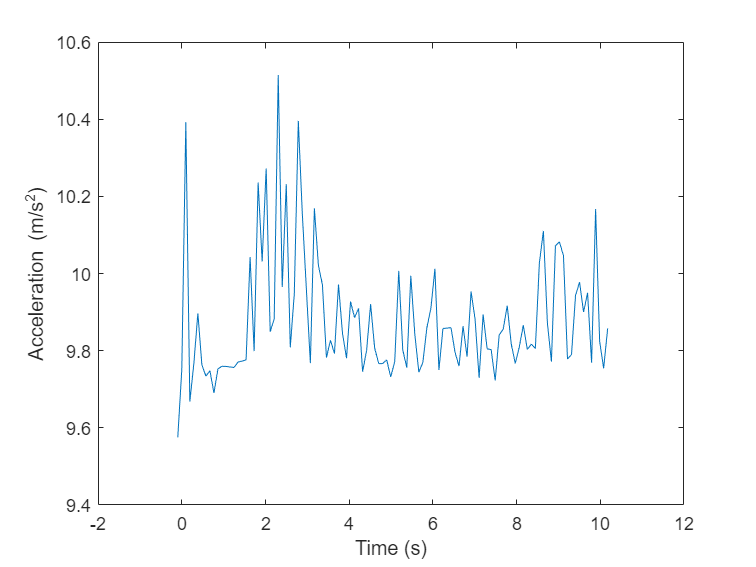

x = a(:,1);
y = a(:,2);
z = a(:,3);

% Calculate and plot magnitude.
mag = sqrt(sum(x.^2 + y.^2 + z.^2, 2));
plot(t, mag);
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

m.Acceleration(1)

Index exceeds the number of array elements. Index must not exceed 0.

 
velocity.X = cumtrapz(1/10,acceleration.X/1000*9.81);
volocity.Y = cumtrapz(1/10,acceleration.Y/1000*9.81);
velocity.Z = cumtrapz(1/10,acceleration.Z/1000*9.81);
position.X = trapz(1/10,velocity.X);
position.Y = trapz(1/10,velocity.Y);
position.Z = trapz(1/10,velocity.Z);